% PLS Regression
% Example data

numRows = size(masterUrine_validate, 1);

% Generate a random permutation of row indices
newOrder = randperm(numRows);

% Use the new row order to scramble the table
masterUrine_validate = masterUrine_validate(newOrder, :);
x = masterUrine_validate(:, 2:end-1);  
X = table2array(x);
Y = masterUrine_validate.Concentration
xtest=masterUrine_Test(:, 2:end-1);
Xtest=table2array(xtest);
% Number of components
num_components = 12;

% Perform PLS regression
[~,~,~,~,beta] = plsregress(X, Y, num_components);

% Predict
Y_pred = [ones(size(X,1),1) X] * beta

Y_pred =     0.1600
    3.6140
    1.0909
   -0.2443
   -0.4183
    1.3027
   -0.3263
    3.0070
    0.9185
    2.1408


Y_pred = round(Y_pred); % Round predictions to nearest integer if appropriate
ytestpred=[ones(size(Xtest,1),1) Xtest] * beta

ytestpred =    -0.6462
   -0.6139
   -0.6611
   -0.6279
   -0.7294
   -0.6593
   -0.6846
   -0.7926
   -0.6286
   -0.8299


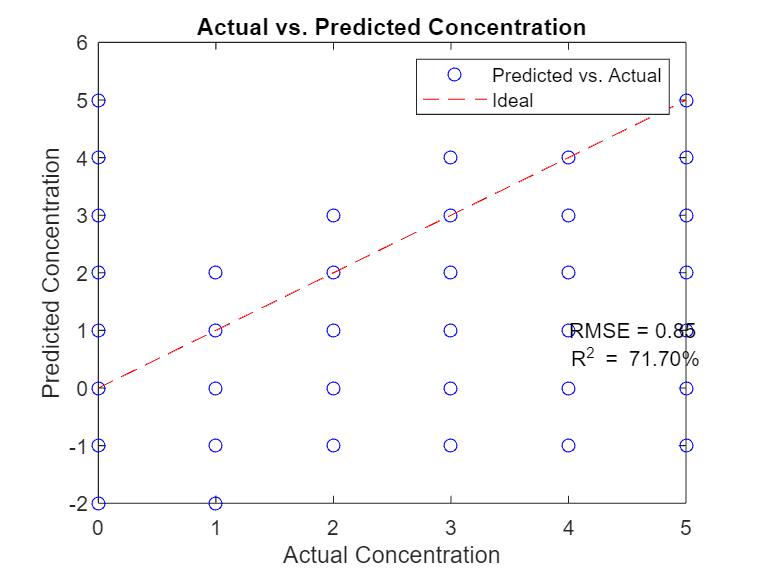


% Compute RMSE
RMSE = sqrt(mean((Y - Y_pred).^2));

% Calculate R-squared
TSS = sum((Y - mean(Y)).^2);
RSS = sum((Y - Y_pred).^2);
Rsquared = 1 - RSS/TSS;

% Now to plot the R-squared value as text on your existing scatter plot
figure;
plot(Y, Y_pred, 'bo');
hold on;
plot([min(Y), max(Y)], [min(Y), max(Y)], 'r--');
text(max(Y)*0.8, max(Y_pred)*0.1, sprintf('R^2 = %.2f%%', Rsquared*100));
text(max(Y)*0.8, max(Y_pred)*0.2, sprintf('RMSE = %.2f', RMSE)); % Display RMSE on the plot
hold off;
xlabel('Actual Concentration');
ylabel('Predicted Concentration');
title('Actual vs. Predicted Concentration');
legend('Predicted vs. Actual', 'Ideal');
xlim([0.00, 5.00]);
ylim([-2.00, 6.00]);